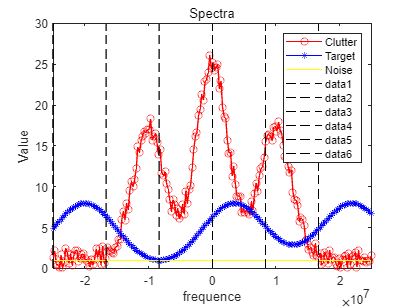

clc
clear 
close all
tic
NT = 4;                  % 发射天线的个数
NR = 4;                  % 接收天线的个数
M = 6;                   % 发射阵元数 子载波个数
K = 2;                   % 子脉冲个数
c=3.0e8;                 % 光速
fc = 10e9;               % 载波频率
lamda = c/fc;            % 波长
d=lamda/2;               % 阵元间距
B = 50e6;                % 每个发射波形的带宽
T = 2e-6;                % 脉冲持续时间
e0 = 1000;               % 每个波形的可用能量
L = 200;                 % 总持续时间中的样本数
Lh = L; Lc = L;
sigma = 0.5;             % 高斯白噪声功率密度
theta = 10;              % 目标方位角

Bb = B/M;                % 子带带宽
Fs = B * 5;              % 采样率
f = linspace(-Fs*0.1, Fs*0.1, L); % 在 0 到 Fs/2 范围内生成 1000 个频率点

% 生成目标、杂波和噪声的频谱
y4=rand(1,length(f))*2.5;
y1=normpdf(f,0,2.5*10^6)*1.5*10^8;
y12=normpdf(f,-1*10^7,2.5*10^6)*1*10^8;
y13=normpdf(f,1*10^7,2.5*10^6)*1*10^8;
y1=(y1+y12+y13+y4);

y11=normpdf(f,-2*10^7,5*10^6);
y22=normpdf(f,0.35*10^7,5*10^6);
y33=normpdf(f,2.2*10^7,5*10^6);
y2=(y11+y22+y33)*10^8;
y3=ones(1,length(f));

% 绘制目标、杂波和噪声的频谱
figure
plot(f,y1,'r-o',f,y2,'b-*',f,y3,'y') %Clutter
legend('Clutter','Target','Noise')
xlabel('frequence')
ylabel('Value')
xlim('tight')
title('Spectra')

% 计算每个子带的宽度和位置
sub_band_width = B / M;
sub_band_centers = linspace(-Fs*0.1 , Fs*0.1, 7);

% 在每个子带中心画竖线
hold on
for i = 1:M
    x = sub_band_centers(i);
    line([x x], ylim, 'Color', 'k', 'LineStyle', '--');
end
hold off